clc;clear;close all;
load Traininginfo.mat %load properties into the model
load Testinginfo.mat
KNN=fitcknn(Traininginfo, 'state') %creates a k nearest neighbor model 

KNN =   ClassificationKNN
           PredictorNames: {'h vs. uh'  'TBint'}
             ResponseName: 'state'
    CategoricalPredictors: []
               ClassNames: {'N'  'T'}
           ScoreTransform: 'none'
          NumObservations: 50
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


prediction=predict(KNN, Testinginfo);
right=prediction==Testinginfo.state;
accuracy=sum(right)/numel(right) %determines the accuracy of the model

accuracy = 0.5800

percentacc=accuracy*100

percentacc = 58.0000

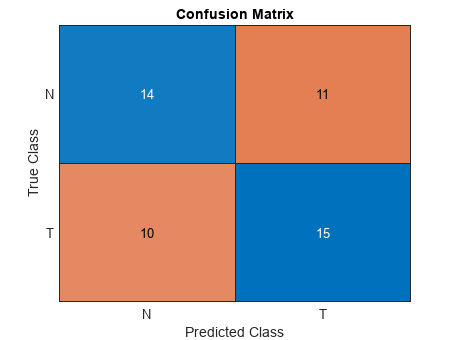


sinfo=Testinginfo.state; %displays the confusion chart
sinfo=cellstr(sinfo);
confusionchart(sinfo,prediction)
title("Confusion Matrix")